# The MathWorks Power Company

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

You are now an employee of the MathWorks power company, your mission is to design an hydropower plant to provide enough electricity to power all of MathWorks data center in its headquarter in Natick. The project would be to buil an aritificial mountain in the shape of MATLAB's membrane logo with a lake at its center. The lake collects water all year and this water is used to generate

[Cool picture]

## Feasibility study

[Picture of the Apple Hill data center]

 **Exercise. **using MATLAB smbolic unit system, define a variable name `avgPower` that represents the average annual power use of the data center

u = symunit;
avgAnnualPower = 100*u.kW

$$avgAnnualPower = 100\,\mathrm{kW}$$

 **Exercise. **Compute the total energy that such data center would be using

annualEnergy = avgAnnualPower * u.year

$$annualEnergy = 100\,\mathrm{kW}\,{\mathrm{year}}_{\mathrm{Julian}}$$

 **Exercise. **Convert this energy use in kWh

annualEnergy = unitConvert(annualEnergy,u.kW*u.hour)

$$annualEnergy = 876600\,h\,\mathrm{kW}$$

 **Exercise. **Estimate the cost of at 0.3$/kWh

annualCost = simplify(annualEnergy * 0.3 / u.kWh)

$$annualCost = 262980$$

### Option 1: Building a dam on the Charles river

riverFlow = 1/3*8.6*u.m^3/u.s

$$riverFlow = 2.8667\,\frac{m^{3}}{s}$$

riverAnnualDischarge = riverFlow * 1*unitConvert(u.year,u.s)

$$riverAnnualDischarge = 90465120\,m^{3}$$

deltaPDam = unitConvert(annualEnergy /riverAnnualDischarge, u.mH2O)

$$deltaPDam = 3.5571\,\mathrm{mH2O}$$

Environmental impact?

### Option 2: Build a large rainwater retention lake

DeltaP = 9.81*1000*10*u.Pa 
VolumeWater = TotalEnergy/DeltaP;
VolumeWater = unitConvert(VolumeWater,u.m^3)
AnnualPrecipitation = 1.11*u.m;
SurfaceCaptation = VolumeWater/AnnualPrecipitation
SurfaceCaptation = unitConvert(SurfaceCaptation,u.km^2)

MathWorks is actually going to Solar and Wind instead: [MathWorks Carbon Neutral Innitiative](https://www.mathworks.com/company/aboutus/carbon-neutral.html)

## Modeling power generated from a retention lake

### Introduction

S = 600 * u.km^2
h = 10 * u.m
plotRetentionLake()

### Mathematical model


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$$


#### Model the rainfall

load NatickWeather.mat
weather
figure
plot(weather,"time","Temp")
hold on
plot(weather,"time","DewPoint")
hold off
title("Temperature and Dew Point in Natick, MA")
ylabel("(^\circ{C})")
xlabel("date")
legend("Air Temperature", "Dew Point","Location","best")
firstDate = datetime(2022,4,11);
Duration = 5;
xlim([firstDate,firstDate+Duration*days]);

% Retime timetable
dailyWeather = retime(weather(:,[1 2 3 5]),"regular","mean",...
    "TimeStep",caldays(1));

% Retime each override variable to same time vector
TT = retime(weather(:,"Rainfall"),dailyWeather.Properties.RowTimes,"sum");
dailyWeather = addvars(dailyWeather,TT.(1),'Before',4,...
    'NewVariableNames',"Rainfall");
clear TT

% Display results
dailyWeather
dailyWeather.E0 = (700*dailyWeather.Temp/(100-42.3)+15*(dailyWeather.Temp-dailyWeather.DewPoint))./(80-dailyWeather.Temp)
plot(dailyWeather.E0)

#### Model the evaporation

#### Model the flow through the turbine

## Helper Functions

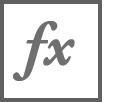`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc